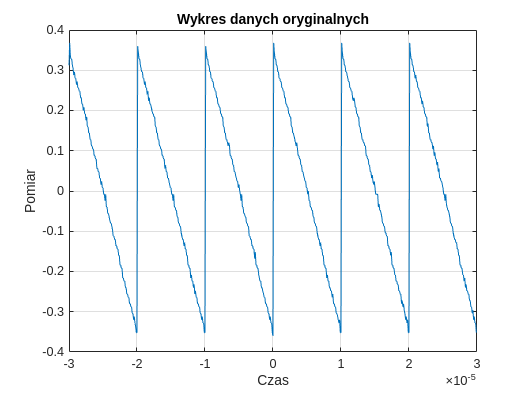

clear;
dane_csv = readtable("L9_CSV.csv");

czas = dane_csv.X;
pomiar = dane_csv.CH1;

figure;
plot(czas, pomiar);
xlabel("Czas");
ylabel("Pomiar");
title("Wykres danych oryginalnych");
grid on;


pomiar_smooth = smoothdata(pomiar);
save("dane_wygladzone.mat", "czas", "pomiar_smooth");

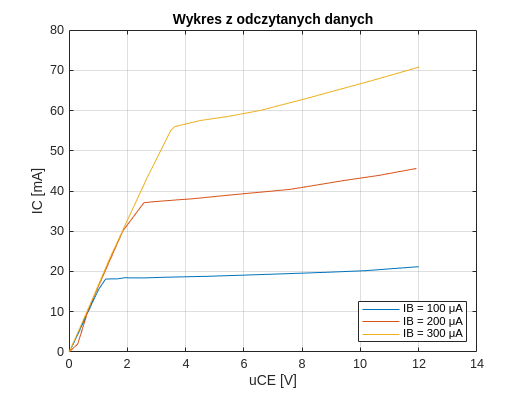

clear;
dane_xlsx = readtable("L9_Excel.xlsx", "VariableNamingRule", "preserve");
dane_xlsx(:, all(ismissing(dane_xlsx))) = [];

uCE1 = dane_xlsx{:,1};
IC1  = dane_xlsx{:,2};
uCE2 = dane_xlsx{:,3};
IC2  = dane_xlsx{:,4};
uCE3 = dane_xlsx{:,5};
IC3  = dane_xlsx{:,6};

valid1 = isfinite(uCE1) & isfinite(IC1);
valid2 = isfinite(uCE2) & isfinite(IC2);
valid3 = isfinite(uCE3) & isfinite(IC3);
uCE1 = uCE1(valid1); IC1 = IC1(valid1);
uCE2 = uCE2(valid2); IC2 = IC2(valid2);
uCE3 = uCE3(valid3); IC3 = IC3(valid3);

uCE_interp = (-0.15:0.01:15)';
IC1_linear = interp1(uCE1, IC1, uCE_interp, "linear", "extrap");
IC2_linear = interp1(uCE2, IC2, uCE_interp, "linear", "extrap");
IC3_linear = interp1(uCE3, IC3, uCE_interp, "linear", "extrap");
IC1_spline = interp1(uCE1, IC1, uCE_interp, "spline", "extrap");
IC2_spline = interp1(uCE2, IC2, uCE_interp, "spline", "extrap");
IC3_spline = interp1(uCE3, IC3, uCE_interp, "spline", "extrap");
IC1_nearest = interp1(uCE1, IC1, uCE_interp, "nearest", "extrap");
IC2_nearest = interp1(uCE2, IC2, uCE_interp, "nearest", "extrap");
IC3_nearest = interp1(uCE3, IC3, uCE_interp, "nearest", "extrap");

figure;
plot(uCE1, IC1); hold on;
plot(uCE2, IC2);
plot(uCE3, IC3);
xlabel('uCE [V]');
ylabel('IC [mA]');
title('Wykres z odczytanych danych');
legend("IB = 100 μA", "IB = 200 μA", "IB = 300 μA", "Location", "southeast");
grid on;


dane_xlsx_interp = table(uCE_interp, IC1_linear, IC2_linear, IC3_linear, IC1_spline, IC2_spline, IC3_spline, IC1_nearest, IC2_nearest, IC3_nearest);
writetable(dane_xlsx_interp, 'Ekstrapolacja.xlsx');